mus = org.fetch('mus');

mus_sess = mus{69};
[var_hwhm, hwhm_vals] = calc_var_hwhm(mus_sess);
var_fwhm = var_hwhm*4;
fwhm_vals = hwhm_vals*2;

[var_fwhm_pj, fwhm_vals_pj] = calc_var_fwhm_pj(mus_sess);

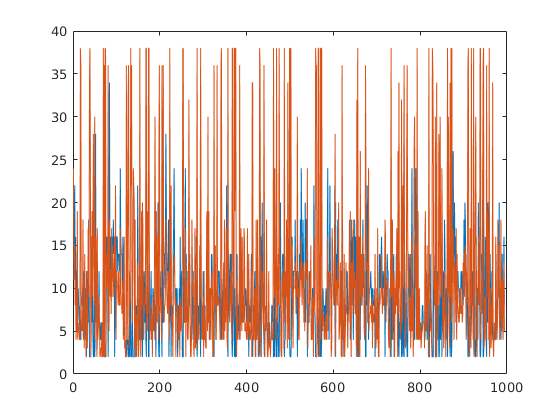

figure;
plot(fwhm_vals);
hold on;
plot(fwhm_vals_pj);

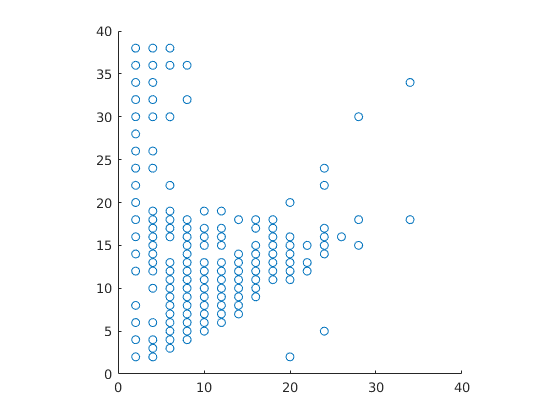

figure;
scatter(fwhm_vals, fwhm_vals_pj);
xlim([0 40]);
ylim([0 40]);
axis square

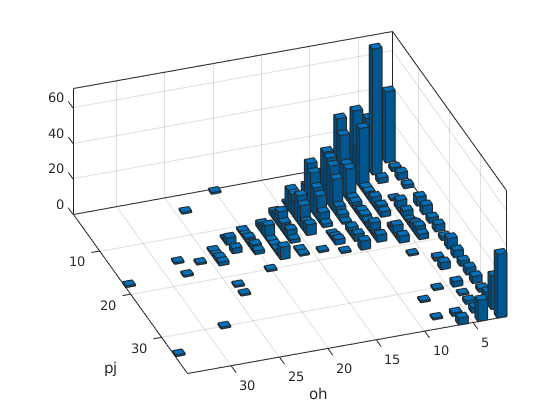

figure;
histogram2(fwhm_vals, fwhm_vals_pj);
xlabel 'oh'
ylabel 'pj'

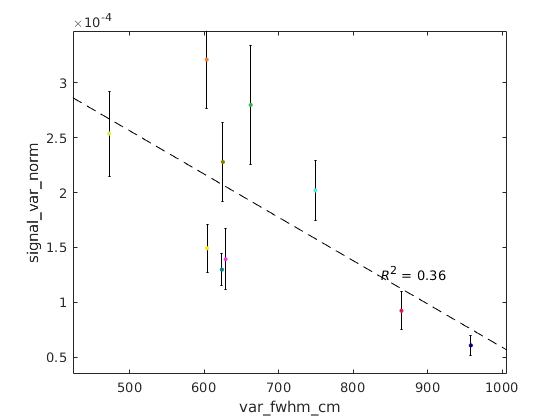

Using only 73 out of 110 sessions
Mouse-aggregated correlations var_fwhm_cm vs. signal_var_norm: adj. R^2 = 0.361
Pearson: -0.657, p = 3.887133e-02, *
Spearman: -0.600, p = 7.311988e-02, n.s.
Kendall: -0.467, p = 7.255015e-02, n.s.


figure;
org.correlogram('var_fwhm_cm', 'signal_var_norm', true, true, true);

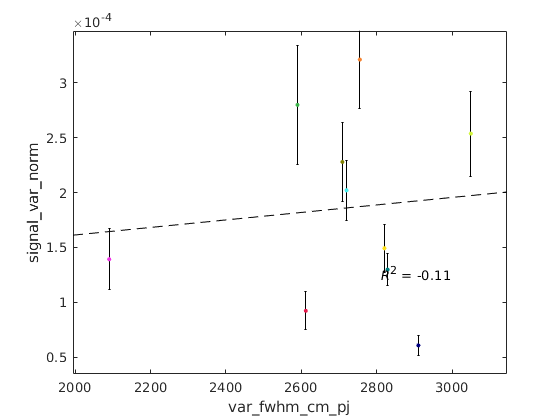

Using only 73 out of 110 sessions
Mouse-aggregated correlations var_fwhm_cm_pj vs. signal_var_norm: adj. R^2 = -0.113
Pearson: 0.103, p = 7.764133e-01, n.s.
Spearman: -0.103, p = 7.850181e-01, n.s.
Kendall: -0.111, p = 7.274895e-01, n.s.


figure;
org.correlogram('var_fwhm_cm_pj', 'signal_var_norm', true, true, true);

function [var_hwhm, hwhm_vals] = calc_var_hwhm(mus)
mus = cell2mat(mus);
[n_cells, n_bins] = size(mus);
assert(n_bins == 40);
[hwhm_r, hwhm_l] = deal(zeros(1, n_cells));
for i = 1:n_cells
    mu_r = mus(i, 1:20);
    mu_l = mus(i, 21:40);
    
    if all(mu_r == mu_r(1))
        hwhm_r(i) = nan;
    else
        hwhm_r(i) = one_hwhm(mu_r);
    end
    
    if all(mu_l == mu_l(1))
        hwhm_l(i) = nan;
    else
        hwhm_l(i) = one_hwhm(mu_l);
    end
end
hwhm_vals = [hwhm_r hwhm_l];
var_hwhm = var([hwhm_r hwhm_l], 'omitnan');
end

function hwhm = one_hwhm(x)
x = x - min(x);
[mx, ix_max] = max(x);
hmx = mx/2;

pre_x = x(1:ix_max);
post_x = x(ix_max:end);

left_bound = find(pre_x < hmx, 1, "last");
if isempty(left_bound)
    left_hw = -inf;
else
    left_hw = ix_max - left_bound;
end

right_bound = find(post_x < hmx, 1, "first");
if isempty(right_bound)
    right_hw = -inf;
else
    right_hw = right_bound - 1;
end

hwhm = max(left_hw, right_hw);
if hwhm < 0
    assert(all(x >= hmx));
    warning('Value never dipped below half max.');
    hwhm = round(numel(x)/2);
end
end

function [var_fwhm, fwhm_vals] = calc_var_fwhm_pj(mus)
mus = cell2mat(mus);
[n_cells, n_bins] = size(mus);
assert(n_bins == 40);
[fwhm_r, fwhm_l] = deal(zeros(1, n_cells));
for i = 1:n_cells
    mu_r = mus(i, 1:20);
    mu_l = mus(i, 21:40);
    
    if all(mu_r == mu_r(1))
        fwhm_r(i) = nan;
    else
        fwhm_r(i) = fwhm_pj(mu_r);
    end
    
    if all(mu_l == mu_l(1))
        fwhm_l(i) = nan;
    else
        fwhm_l(i) = fwhm_pj(mu_l);
    end
end
fwhm_vals = [fwhm_r fwhm_l];
var_fwhm = var([fwhm_r fwhm_l], 'omitnan');
fprintf('\n');
end

function fwhm = fwhm_pj(x)
SmoothRF = x;
RF = [];
ResampleRate = 1;

try
    [peak,positPeak,TopW,HW,Slopes1090,INFR,OUTFR]=slopeAndHalfWidthFinderNEW(RF,SmoothRF,ResampleRate);
    fwhm = HW;
catch
    fprintf('*');
    fwhm = nan;
end
end